#                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        Harmonic Oscillator

## Basic Case - Single DOF, no damping, no external force

One mass, one spring, single DOF, no damping, no external force

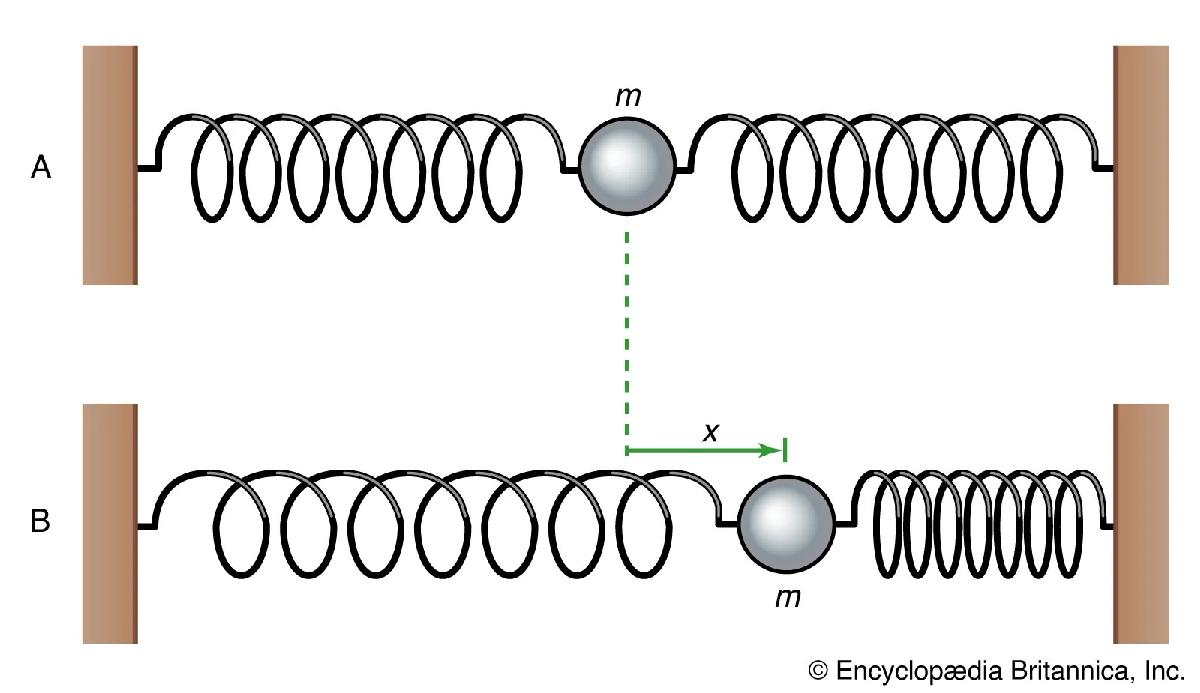

The equation of motion for this sistem is:

##                         
$$m \ddot x + kx = 0$$


With the solution:

##                 
$$x(t) = A \cdot sin(\omega t + \phi)$$


where A and $\phi$ are derived from initial conditions, and $\omega = \sqrt \frac{k}{m}$

This analitical solution can be plotted immidiately:

a = 1; % initial conditions
phi = 0; %initial conditions
f = 1; %[Hz] the frequency is determined by ration between k and m
omega = 2*pi*f;

t_an = linspace(0,10,1001);
x_an = a * sin(omega*t_an + phi);

figure
plot(t_an,x_an)
xlabel('time [sec]')
ylabel('sin(\omega t)')
title ('Basic Harmonic oscillation')
hold on
grid on

## Numerical Integration - Basic case

There is of course no need to solve this numerically. But it would be useful to start checking numerical simulation on the simple, analitical case.

System parameters:

Normalized mass: m = 1 

for f=1[Hz] -> $\omega = 2 \cdot \pi \cdot f = \sqrt \frac {k}{m} ; m=1; f =1 \Rightarrow (2\cdot\pi)^2 = k$

m = 1;
k = 4*pi*pi; %so that f=1[hz]

Initial conditions:

x0 = 0

$\dot x = \omega \cdot cos(\omega t)$ for f=1[Hz] => $\omega = 2\pi$

x0 = 0; % sin
xdot0 = 2*pi; % cos

the equations would be:


$$\ddot x = -\frac{k}{m}\cdot x
$$


and x and its first derivative are determined by integration.

### The simplest and the most basic integration is the simple summation:


$$y_{i+1} = y_i + \dot y_i \cdot \Delta t$$


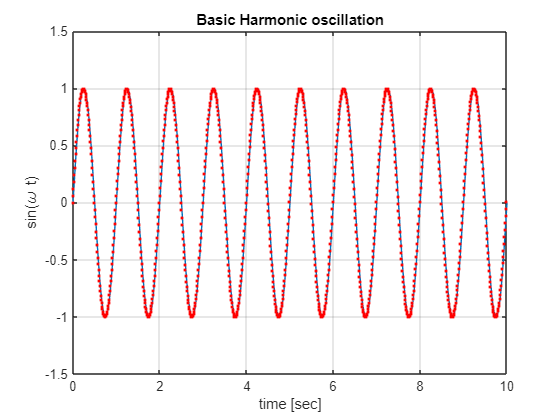

dt = 0.01; %integration interval [sec]
%initialization
t_num(1) = 0;
x_num(1) = x0;
xdot(1) = xdot0;
%iterative solution
for ind = 1:1000
    xdotdot(ind) = -k/m*x_num(ind);

    t_num(ind+1) = t_num(ind) + dt;
    xdot(ind+1) = xdot(ind) + xdotdot(ind) * dt;
    x_num(ind+1) = x_num(ind) + xdot(ind+1) * dt; %the first derivative is already calculated
end

plot(t_num,x_num,'r.')

The simplest method gives good enough results for the simple case, given integration interval small enough. As the complexity of the problem progresses, we will need to employ smarter solutions for numeric integration.

### Average error

The error between the numerical calculation and the theoretical one.

err = x_num - x_an;
err2 = err.*err;
sumerr = sum(err2)

sumerr = 0.0180

sumerr2n = sumerr/length(t_num)

sumerr2n = 1.7956e-05

## Damped

One mass, one spring, single DOF, damping proportional to velocity, no external force

The equation of motion for this sistem is:

##                         
$$m \ddot x + b \dot x + kx = 0$$


With the solution:

##                 
$$x(t) = A \cdot e^{-t/\tau} \cdot  sin(\omega t + \phi)$$


where A and $\phi$ are derived from initial conditions, and $\omega = \sqrt {\frac{k}{m}-\left(\frac{b}{2m}\right)^2$ and $\tau = \frac{2m}{b}$

This analitical solution can be plotted immidiately. Keeping the same prameters as before, only adding damping.

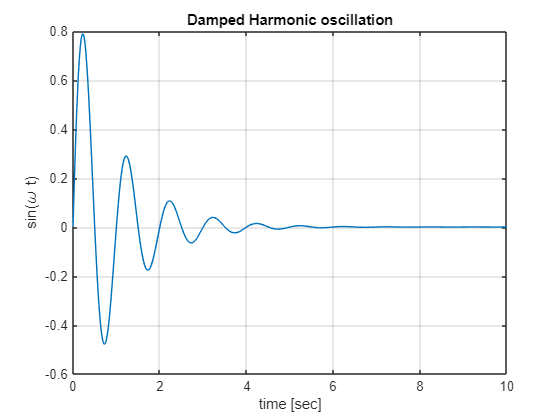

a = 1; % initial conditions
phi = 0; %initial conditions
f = 1; %[Hz] the frequency is determined by ration between k and m
omega = 2*pi*f;
tau = 1;

t_an = linspace(0,10,1001);
x_an = a * exp(-t_an/tau) .* sin(omega*t_an + phi);

figure
plot(t_an,x_an)
xlabel('time [sec]')
ylabel('sin(\omega t)')
title ('Damped Harmonic oscillation')
hold on
grid on

In terms of dynamic sistem the equation of motion is written:

##                      
$$\ddot x + 2\zeta \omega_n \dot x + \omega_n^2 = 0$$


For such system the critical damping is $\zeta = 0.7$

It was previously chosen for f=1[Hz] -> $f = 1[=Hz]   \Rightarrow \omega = 2 \pi$ and m =1 therefore $\tau = \frac{2m}{b} = \frac{2 m}{2\zeta \omega_n} =  \frac{1}{2\pi \zeta}$

We can use the slider tool to see the change in the system behaiviour as we change the damping coefficient

a = 1; % initial conditions
phi = 0; %initial conditions
f = 1; %[Hz] the frequency is determined by ration between k and m
omega_n = 2*pi*f;

zeta = 0;
tau = 1/(2*pi*zeta)

tau = Inf

disp_str = sprintf('zeta = %3.2f', zeta);

t_ch = linspace(0,10,1001);
x_ch = a * exp(-t_ch/tau) .* sin(omega_n*t_ch + phi);

figure
plot(t_ch,x_ch, DisplayName=disp_str)
xlabel('time [sec]')
ylabel('sin(\omega t)')
title ('Damped Harmonic oscillation')
hold on
grid on
legend show

## Numerical Integration - Damped

This case too does not need numeric solution, it will be used as simple case for checking the numerical solutions.

System parameters  as in previous case:

Normalized mass: m = 1 

for natural frequency f=1[Hz] -> $k = \omega_n^2 = 4\pi^2 $

Damping will vary.

m = 1;
k = omega_n*omega_n; %so that f=1[hz]


$$b = 2 \cdot \zeta \cdot \omega_n;  \omega_n = 2\pi f$$


b = 2 * zeta * omega_n;

Initial conditions as previous:


$$x_0 = 0; \dot x_0 = 2\pi$$


x0 = 0; % sin
xdot0 = 2*pi; % cos

the equations would be:


$$\ddot x = -\frac{k}{m}\cdot x - \frac{b}{m} \dot x
$$


and x and its first derivative are determined by integration.

### The simplest and the most basic integration is the simple summation:


$$y_{i+1} = y_i + \dot y_i \cdot \Delta t$$


dt = 0.01; %integration interval [sec]
%initialization
t_num(1) = 0;
x_num(1) = x0;
xdot(1) = xdot0;

%iterative solution
for ind = 1:1000
    xdotdot(ind) = -k/m*x_num(ind) - b/m*xdot(ind);

    t_num(ind+1) = t_num(ind) + dt;
    xdot(ind+1) = xdot(ind) + xdotdot(ind) * dt;
    x_num(ind+1) = x_num(ind) + xdot(ind+1) * dt; %the first derivative is already calculated
end
plot(t_num,x_num,'r.',Displayname = 'int square local')

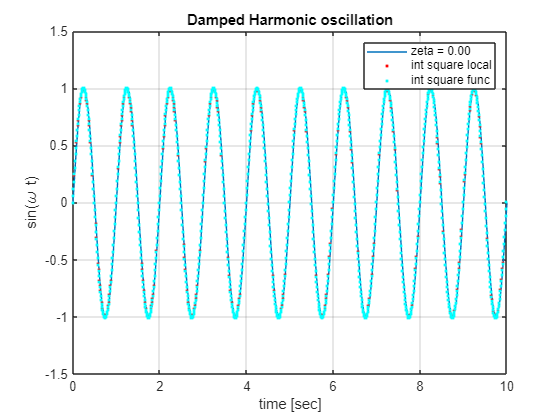

%iterative solution - using vectorial notation
t_is(1) = 0;
x_is(1) = x0;
xdot_is(1) = xdot0;
for ind = 1:1000
    xi(1) = x_num(ind);
    xi(2) = xdot(ind);
    xi_dot(1) = xdot(ind);
    xi_dot(2) = -k/m*x_is(ind) - b/m*xdot_is(ind);

    t_is(ind+1) = t_num(ind) + dt;
    xi_p1 = int_step_square(xi,xi_dot, dt);

    x_is(ind+1) = xi_p1(1);
    xdot_is(ind+1) = xi_p1(2);

end

plot(t_is,x_is,'c.',Displayname = 'int square func')

In this case the simple summation does not yield satisfactory results for large values of zeta. Making the integration step smaller does not povide better results. Therefore implementation of more sofisticated numerical integration scheme is the next logical step. 

#### Trapezoidal numerical integration

dt = 0.01; %integration interval [sec]
% initialization
t_trpz(1) = 0;
x_trpz(1) = x0;
xdot_trpz(1) = xdot0;
% first step
xdotdot(1) = -k/m*x_num(1) - b/m*xdot(1);
t_trpz(2) = t_trpz(1) + dt;
xdot_trpz(2) = xdot_trpz(1) + xdotdot(1) * dt;
x_trpz(2) = x_num(1) + xdot(2) * dt;
% iterative solution starts at second step
for ind = 2:1000
    xdotdot(ind) = -k/m*x_trpz(ind) - b/m*xdot_trpz(ind);

    t_trpz(ind+1) = t_trpz(ind) + dt;

    xdot_trpz(ind+1) = xdot_trpz(ind) + (xdotdot(ind) + xdotdot(ind-1))/2 * dt;
    x_trpz(ind+1) = x_trpz(ind) + (xdot_trpz(ind+1) + xdot_trpz(ind))/2 * dt; %the first derivative is already calculated
end

% plot(t_trpz,x_trpz,'g.')